# Import AUTOSAR Package into Adaptive Component Model

Import and reference shared ARXML element definitions for the Adaptive Platform.

## Add AUTOSAR Adaptive Element Definitions to Model

When developing an AUTOSAR adaptive software component in Simulink, you can import AUTOSAR element definitions that are common to many components. After you create an AUTOSAR adaptive component model, you import the definitions from AUTOSAR XML (ARXML) files that contain packages of AUTOSAR shared elements. To help implement the component behavior, you want to reference predefined elements such as service interfaces, with their associated events and namespaces, and data types.

Suppose that you are developing an AUTOSAR adaptive software component model. You want to import predefined adaptive platform type elements that are shared by multiple product lines and teams. This example uses AUTOSAR importer function [`updateAUTOSARProperties`](docid:autosar_ref.mw_533f6623-353e-405c-a6f1-fe23f99745f3) to import definitions from shared descriptions file `Adaptive_PlatformTypes.arxml` into example model `autosar_LaneGuidance`.

modelName = 'autosar_LaneGuidance';
open_system(modelName);
ar = arxml.importer('Adaptive_PlatformTypes.arxml');
updateAUTOSARProperties(ar,modelName);

The function copies the elements in the specified ARXML files to the AUTOSAR Dictionary of the specified model. If you import data types, the function also creates data objects, in a data dictionary (if available) or in the base workspace, for the imported types.

The function generates an HTML report listing the workspace changes and the element additions. Here are the Simulink workspace changes, reflecting creation of data objects to represent previously undefined adaptive platform types.

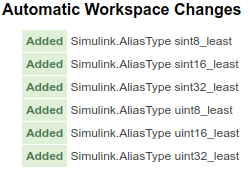

Here are the AUTOSAR element additions. Notice that the function created a new AUTOSAR package named `AUTOSAR_Platform`. Based on the imported adaptive platform types, the function populated the package with AUTOSAR software base types and AUTOSAR implementation data types.

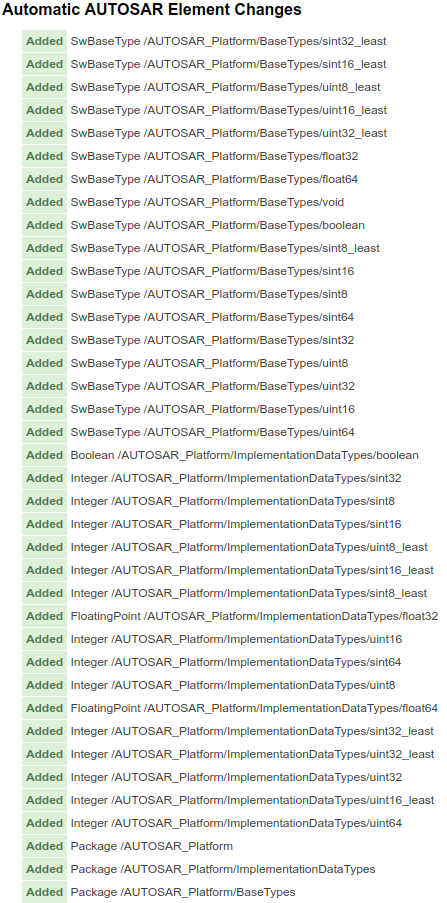

The package changes are reflected in the AUTOSAR Dictionary views of the package tree. If you open the AUTOSAR Dictionary and navigate to an individual service interface, you can click the horizontal ellipsis to the right of the **Package** field to view the current package tree.

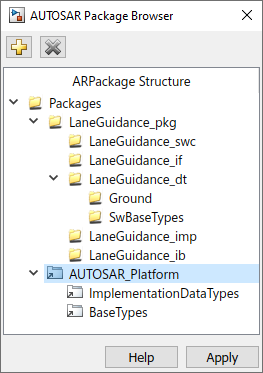

## Reference and Configure Imported AUTOSAR Adaptive Elements

After importing AUTOSAR elements into the adaptive software component model, you can reference and configure the elements in the same manner as any AUTOSAR Dictionary element.

If you imported data types, you can reference the types from your model blocks. For example, open a Simulink port block in your model and select the **Signal Attributes** tab. Expand the **Data type** list of values and notice that the imported data types are available for selection.

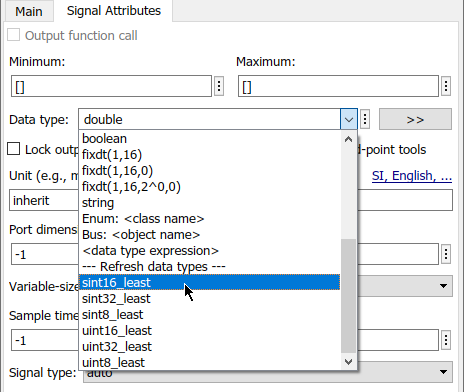

If you have Simulink Coder and Embedded Coder software, you can generate AUTOSAR-compliant C++ code and export ARXML descriptions from the adaptive component model. The C++ code reflects references from model blocks to the imported adaptive elements. Export preserves the file structure and content of the shared descriptions files from which you imported definitions. In ARXML files other than the shared description files, ARXML descriptions reference the shared element definitions where required.

## Related Links

- [`updateAUTOSARProperties`](docid:autosar_ref.mw_533f6623-353e-405c-a6f1-fe23f99745f3)

- [Import AUTOSAR Adaptive Software Descriptions](docid:autosar_ug.mw_e0c0e04c-464a-49c8-99e5-c6614513b41d)

- [AUTOSAR ARXML Importer](docid:autosar_ug.bt4nufq)

*Copyright 2019 The MathWorks, Inc.*